# compare ssfr and stellar mass in profiles: 3d vs. projected. 

We generated 3d profiles as well as 3 projected profiles. We'll compare them to see whether the projection can explain the mis-match with observations. 

## Load in the projected profiles


global DEFAULT_MATFILE_DIR
global simDisplayName

fnameProj=[DEFAULT_MATFILE_DIR '/ssfr0_stellarMass_radProfiles_projected_yangSample_fiber_' simDisplayName];
load(fnameProj)
profProjYF=profStruct;

clear profStruct;

fname3d=[DEFAULT_MATFILE_DIR '/ssfr0_stellarMass_radProfiles_projected_yangSample_' simDisplayName];

load(fname3d);
profY=profStruct;

clear profStruct;

## add in the obs data


load([DEFAULT_MATFILE_DIR '/ssfr_rpos_dataGrab.mat'])

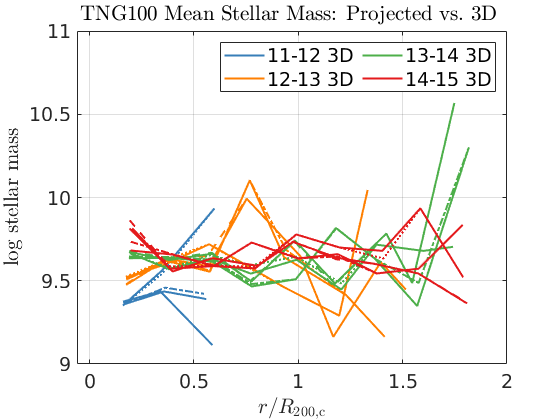




global DEFAULT_PRINTOUT_DIR
outDir=[DEFAULT_PRINTOUT_DIR '/obsComp'];

cc=brewermap(8,'Set1');
lt={'--',':','-.'};
hf=figure('color','w');
h=[];


for i=1:4 % run over host masses.
    
    
    %         xx=prof3d(k).starMass(i).xMedian;
    %         %y=prof3d(k).starMass(i).yMedian;
    %         y1=log10(prof3d(k).starMass(i).yQuarts(2,:));
    %         y2=log10(prof3d(k).starMass(i).yQuarts(3,:));
    %         yy=log10(prof3d(k).starMass(i).yMedian);
    
%     xc=0.05;
%     yc=log10(prof3d.starMassC(i).yMedian);
%     ycP=log10(prof3d.starMassC(i).yQuarts(2,:))-yc;
%     ycN=yc-log10(prof3d.starMassC(i).yQuarts(2,:));
    
    switch i
        case 1
            colo=cc(2,:);
            nam='11-12';
        case 2
            colo=cc(5,:);
            nam='12-13';
            
        case 3
            colo=cc(3,:);
            nam='13-14';
            
        case 4
            colo=cc(1,:);
            nam='14-15';
            
    end
    
    for k=1:3
        xx=profY(k).starMass(i).xMedian;
        y=profY(k).starMass(i).yMedian;
        y1=log10(y-0.5*profY(k).starMass(i).yStanDev);
        y2=log10(y+0.5*profY(k).starMass(i).yStanDev);
        yy=log10(profY(k).starMass(i).yMedian);
        
        
        h(i)=plot(xx,yy,'color',colo,'DisplayName',[nam ' 3D'],"LineStyle",'-','linewidth',1.5);
        hold on
        
        % errorbar(xc,yc,ycN,ycP,'o','color',colo)
    
    % plot projected
    
        xxp=profProjYF(k).starMass(i).xMedian;
        yp=profProjYF(k).starMass(i).yMedian;
        y1p=log10(y-0.5*profProjYF(k).starMass(i).yStanDev);
        y2p=log10(y+0.5*profProjYF(k).starMass(i).yStanDev);
        yyp=log10(profProjYF(k).starMass(i).yMedian);
        
        
        
        
        plot(xxp,yyp,'color',colo,'DisplayName',nam,"LineStyle",lt{k},'linewidth',1.5);
        
        
    end
    
end

grid
set(gca,'Fontsize',14)
%
hl=legend(h,'numcolumns',3,'location','northEast','fontsize',14);
xlim([-0.06 2])
ylim([9 11])
xlabelmine('$r/R_\mathrm{200,c}$');
ylabelmine('log stellar mass');
titlemine([simDisplayName ' Mean Stellar Mass: Projected vs.\@ 3D '] );
%
printout_fig(gcf,['mean_stellarMass_radProf_projected_NewSample_' simDisplayName],'dir',outDir)

## sfr

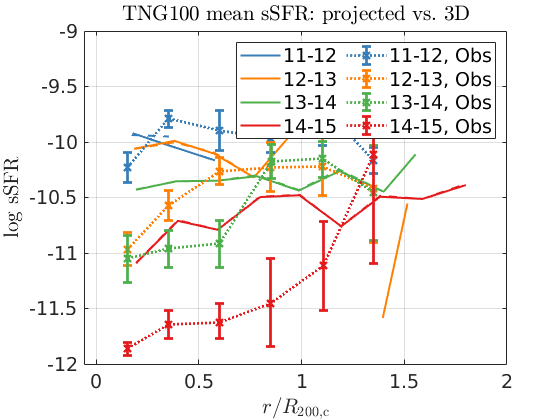

hf=figure('color','w');
h=[];

for i=1:4
    
            xx=profY(k).ssfrAvg(i).xMean;
            y=profY(k).ssfrAvg(i).yMean;
            y1=log10(y-0.5*profY(k).ssfrAvg(i).yStanDev);
            y2=log10(y+0.5*profY(k).ssfrAvg(i).yStanDev);
            yy=log10(profY(k).ssfrAvg(i).yMean);
    %
%     xx=prof3d(k).ssfrAvg(i).xMedian;
%     %y=prof3d(k).ssfrAvg(i).yMedian;
%     y1=log10(prof3d(k).ssfrAvg(i).yQuarts(2,:));
%     y2=log10(prof3d(k).ssfrAvg(i).yQuarts(3,:));
%     yy=log10(prof3d(k).ssfrAvg(i).yMedian);
%     
%     xc=0.05;
%     yc=log10(prof3d.ssfrAvgC(i).yMedian);
%     ycP=log10(prof3d.ssfrAvgC(i).yQuarts(2,:))-yc;
%     ycN=yc-log10(prof3d.ssfrAvgC(i).yQuarts(2,:));
    
    switch i
        case 1
            colo=cc(2,:);
            nam='11-12';
        case 2
            colo=cc(5,:);
            nam='12-13';
            
        case 3
            colo=cc(3,:);
            nam='13-14';
            
        case 4
            colo=cc(1,:);
            nam='14-15';
            
    end
    
    h(i)=plot(xx,yy,'-','color',colo,'DisplayName',nam,'linewidth',1.5);
        hold on
    
        
%         if k==1
%         
%         %errorbar(xx,yy,y1,y2,'color',colo)
%         patch([xx fliplr(xx)],[y1 fliplr(y2)],colo,...
%             'facealpha',0.1,'edgecolor','none')
%     elseif k==2 && i==1
%         
%         h(end+1)=plot(xx,yy,'color',colo,'DisplayName','TNG50-2',"LineStyle",lt);
%     elseif k==3 && i==1
%         h(end+1)=plot(xx,yy,'color',colo,'DisplayName','TNG50-3',"LineStyle",lt);
%     else
%         plot(xx,yy,'color',colo,'DisplayName',nam,"LineStyle",lt);
%         
%         
%     end
%     
  %  errorbar(xc,yc,ycN,ycP,'o','color',colo)
    
    for k=1
        
            xxP=profProjYF(k).ssfrAvg(i).xMean;
            yP=profProjYF(k).ssfrAvg(i).yMean;
            y1P=log10(y-0.5*profProjYF(k).ssfrAvg(i).yStanDev);
            y2P=log10(y+0.5*profProjYF(k).ssfrAvg(i).yStanDev);
            yyP=log10(profProjYF(k).ssfrAvg(i).yMean);
        
            plot(xxP,yyP,'color',colo,'DisplayName',nam,"LineStyle",lt{k},'linewidth',1.5);
        
        
    end
    
    
end

for i=5:8
    
    switch i
        case 5
            xx=obsCat.ssfr_rpos_11_main(2,:);
            yy=obsCat.ssfr_rpos_11_main(1,:);
            pos=obsCat.ssfr_rpos_11_top(1,:)-obsCat.ssfr_rpos_11_main(1,:);
            neg=obsCat.ssfr_rpos_11_main(1,:)-obsCat.ssfr_rpos_11_bottom(1,:);
            colo=cc(2,:);
            nam='11-12, Obs';
            
%             ccc=obsCat.ssfr_rpos_11_central(1,2);
%             cp=obsCat.ssfr_rpos_11_central(1,3)-obsCat.ssfr_rpos_11_central(1,2);
%             cm=obsCat.ssfr_rpos_11_central(1,2)-obsCat.ssfr_rpos_11_central(1,1);
        case 6
            xx=obsCat.ssfr_rpos_12_main(2,:);
            yy=obsCat.ssfr_rpos_12_main(1,:);
            pos=obsCat.ssfr_rpos_12_top(1,:)-obsCat.ssfr_rpos_12_main(1,:);
            neg=obsCat.ssfr_rpos_12_main(1,:)-obsCat.ssfr_rpos_12_bottom(1,:);
            colo=cc(5,:);
            nam='12-13, Obs';
            
%             ccc=obsCat.ssfr_rpos_12_central(1,2);
%             cp=obsCat.ssfr_rpos_12_central(1,3)-obsCat.ssfr_rpos_12_central(1,2);
%             cm=obsCat.ssfr_rpos_12_central(1,2)-obsCat.ssfr_rpos_12_central(1,1);
            
        case 7
            xx=obsCat.ssfr_rpos_13_main(2,:);
            yy=obsCat.ssfr_rpos_13_main(1,:);
            pos=obsCat.ssfr_rpos_13_top(1,:)-obsCat.ssfr_rpos_13_main(1,:);
            neg=obsCat.ssfr_rpos_13_main(1,:)-obsCat.ssfr_rpos_13_bottom(1,:);
            colo=cc(3,:);
            nam='13-14, Obs';
            
%             ccc=obsCat.ssfr_rpos_13_central(1,2);
%             cp=obsCat.ssfr_rpos_13_central(1,3)-obsCat.ssfr_rpos_13_central(1,2);
%             cm=obsCat.ssfr_rpos_13_central(1,2)-obsCat.ssfr_rpos_13_central(1,1);
%             
        case 8
            xx=obsCat.ssfr_rpos_14_main(2,:);
            yy=obsCat.ssfr_rpos_14_main(1,:);
            pos=obsCat.ssfr_rpos_14_top(1,:)-obsCat.ssfr_rpos_14_main(1,:);
            neg=obsCat.ssfr_rpos_14_main(1,:)-obsCat.ssfr_rpos_14_bottom(1,:);
            colo=cc(1,:);
            nam='14-15, Obs';
            
%             ccc=obsCat.ssfr_rpos_14_central(1,2);
%             cp=obsCat.ssfr_rpos_14_central(1,3)-obsCat.ssfr_rpos_14_central(1,2);
%             cm=obsCat.ssfr_rpos_14_central(1,2)-obsCat.ssfr_rpos_14_central(1,1);
            
    end
    
    
    
    
    h(i)=errorbar(xx,yy,neg,pos,'x:','color',colo,...
        'DisplayName',nam,'LineWidth',2);
    
   % errorbar(0,ccc,cm,cp,'x','color',colo)
end


set(gca,'Fontsize',14)
grid
hl=legend(h,'numcolumns',2,'location','northEast','fontsize',14);
 xlim([-0.06 2])
 ylim([-12 -9])
xlabelmine('$r/R_\mathrm{200,c}$');
ylabelmine('log sSFR');
titlemine([simDisplayName ' mean sSFR: projected vs.\@ 3D'] );

printout_fig(gcf,['mean_ssfr_radProf_projected_newSample_' simDisplayName],'dir',outDir)

%printout_fig(gcf,'median_ssfr0_radProf_TNG50','dir',outDir)
%printout_fig(gcf,'median_ssfr_radProf')